# **Vision Artificial. GIEC y GITT.**

# **	Sistemas de Vision Artificial. GIC, GII y GISI.**

**	Miguel Angel Garcia, Juan Manuel Miguel, Sira Palazuelos. **

**  Departamento de Electrónica. Universidad de Alcalá. SPAIN.**

# Tema 5: Transfer Learning

# **Parte I. **GoogLeNet

## GoogLeNet

El primer paso va a ser estudiar las características de GoogLeNet.

GoogLeNet es un modelo preentrenado que ha sido entrenado en un subconjunto de la base de datos ImageNet. El modelo se ha entrenado con más de un millón de imágenes, tiene 144 capas y puede clasificar imágenes en 1.000 categorías de objetos (por ejemplo, teclado, ratón, lápiz y muchos animales).

Esta función requiere el paquete de soporte **Deep Learning Toolbox™ Model *****for GoogLeNet Network*****.** Si no ha instalado el paquete de soporte, la función proporciona un enlace de descarga.

Con el siguiente código se cargar la red preentrenada GoogLeNet y sus clases e inspeccionando la primera capa se obtiene el tamaño (dimensiones) de las imágenes que la red espera como entrada. 

clear all
 
% 1. Cargar la red preentrenada GoogLeNet y sus clases
[net, classNames] = imagePretrainedNetwork("googlenet");% para versiones R2024a o superiores 

% 2. Obtener el tamaño de entrada requerido por la red ([224 224 3])
inputSize = net.Layers(1).InputSize;


## predicción de GoogLeNet

Se van a obtener las precciones de la red GoogLeNet para todas las imágenes de la carpeta `"images"`.

**Se pide:**

- Cargue todas las imágenes del directorio `"images"` en un almacen de imágenes de Matlab con la función [imageDatastore](https://es.mathworks.com/help/releases/R2026b/matlab/ref/matlab.io.datastore.imagedatastore.html).

- Redimensione todas las imágenes a la vez al tamaño de entrada de la red utilizando la función [augmentedImageDatastore](https://es.mathworks.com/help/releases/R2026b/deeplearning/ref/augmentedimagedatastore.html).

- Relizar la predicción para todas las imágenes en lote con la función [minibatchpredict](https://es.mathworks.com/help/deeplearning/ref/minibatchpredict.html). 

- Convertir las puntuaciones devueltas por minibatchpredict (`scores`) a etiquetas con la función [scores2label](https://es.mathworks.com/help/deeplearning/ref/scores2label.html).

**Nota**: Para realizar una predicción con una sola imagen, hay que utilizar la función [`predict`](https://es.mathworks.com/help/deeplearning/ref/dlnetwork.predict.html). Esta función solo admite los siguientes formatos: `dlarray, full double/single/logical array, `o un compatible` gpuArray`. Si la imagen se carga con imresize el tipo de datos es `uint8`, luego para realizar la predicción con la red neuronal se debe convertir al tipo de datos [`single`](https://es.mathworks.com/help/matlab/ref/single.html).


% 3. Cargar las imágenes desde el directorio 'images'
imageFolder = "images";

images_ds = imageDatastore( ); % RELLENAR AQUÍ
numImages = numel(images_ds.Files);

if numImages == 0
    error("No se encontraron imágenes en el directorio '%s'.", imageFolder);
end


% 4. Redimensionar y forzar 3 canales (RGB) en todas las imágenes
images_net = augmentedImageDatastore( ); % RELLENAR AQUÍ

% 4. Realizar las predicciones
% minibatchpredict devuelve una matriz con las probabilidades de cada clase por imagen
scores = minibatchpredict( ); % RELLENAR AQUÍ

[Pred_Label, maxScores] = scores2label( ); % RELLENAR AQUÍ

Finalmente se muestran las imágenes una a una avanzando al pulsar una tecla cualquiera.

% 6. Mostrar las imágenes una a una avanzando al pulsar una tecla
fig = figure;

for i = 1:numImages
    % Comprobar que el usuario no haya cerrado la ventana manualmente
    if ~isvalid(fig)
        break;
    end

    img = readimage(images_ds, i);

    texto = sprintf('%s (%.2f%%)', string(Pred_Label(i)), 100*maxScores(i));

    % Superponer texto
    Iout = insertText(img,[10 10], texto, FontSize=24, BoxColor='black', TextColor='white');

    imshow(Iout)

    % Esperar pulsación de tecla (ignora clics de ratón)
    if i < numImages
        while waitforbuttonpress ~= 1
            if ~isvalid(fig), break; end
        end
    end
end


# **Parte II.** Transfer Learning

La transferencia del aprendizaje es un proceso que consiste en elegir una red de deep learning preentrenada y ajustarla para aprender una tarea nueva. Utilizar la transferencia del aprendizaje es normalmente un proceso más rápido y sencillo que entrenar una red desde cero. Puede transferir de forma rápida las características aprendidas a una nueva tarea con menos cantidad de datos.

## Flujo de trabajo típico de transferencia del aprendizaje 

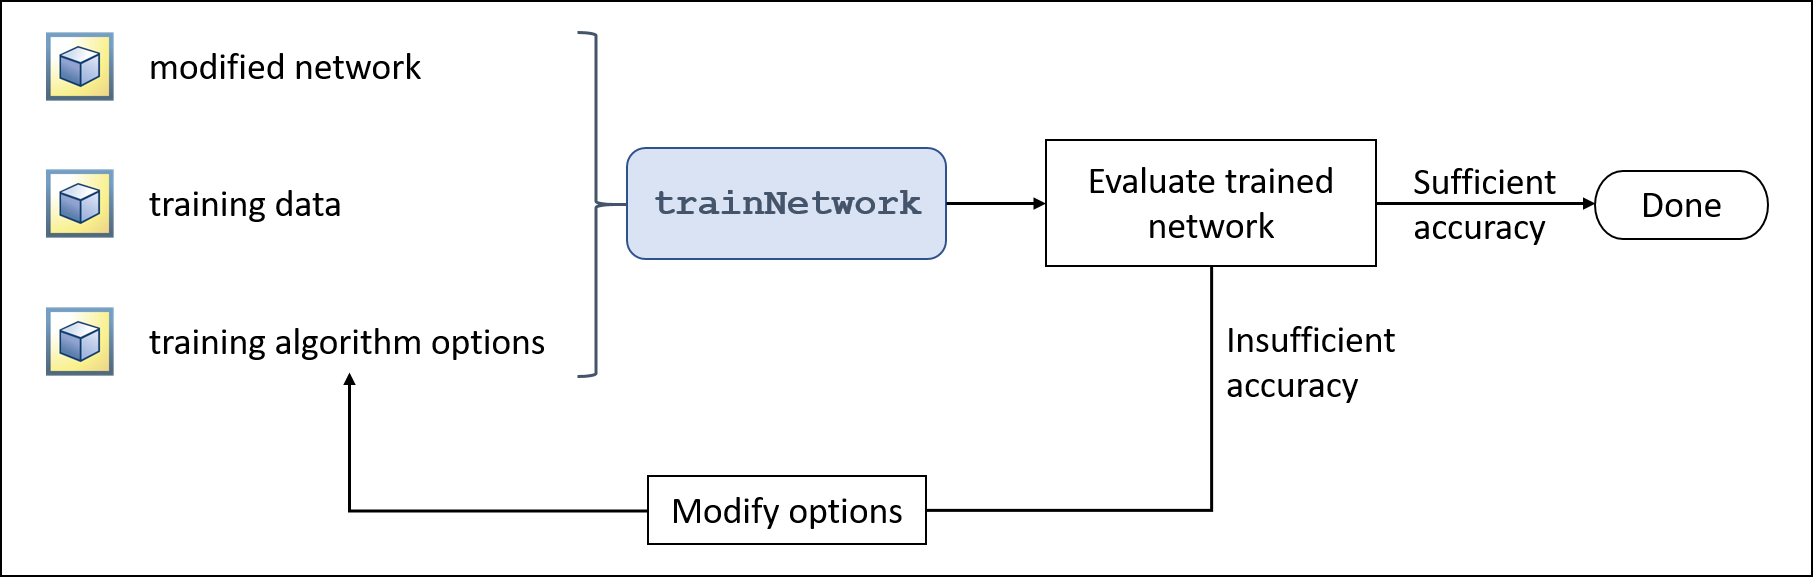

Para realizar la transferencia del aprendizaje necesita crear tres componentes:

- `modified network.` Un arreglo de capas que representan la arquitectura de red.  Para la transferencia del aprendizaje, este arreglo de capas se crea  modificando una red preexistente, como **GoogLeNet**.  

- `training data. `Imágenes con **etiquetas** conocidas, para utilizarlas como datos de entrenamiento. Por lo general se proporcionan como **almacén de datos**.

- `training algorithm options.`Una variable que contenga las **opciones** que controlan el comportamiento del algoritmo de entrenamiento.

Estos tres componentes se proporcionan como entradas a la función, [`trainnet`](https://es.mathworks.com/help/deeplearning/ref/trainnet.html) que devuelve la red entrenada como salida. 

Se recomienda probar el rendimiento de la red entrenada que acaba de crear. Si no es el adecuado, intente ajustar alguna de las opciones de  entrenamiento y volver a realizar el entrenamiento.  

clear all
close all
clc

# `1. Training Data`

### **    1.1) Extraer datos**

En este ejemplo se va a utiliza un conjunto de datos de varios miles de fotos de flores. El conjunto de datos de flores (Flowers`/)` contiene cinco subdirectorios, uno por clase:

- `  daisy/ (margarita)`

- `  dandelion/ (diente de león)`

- `  roses/ (rosas)`

- `  sunflowers/ (girasoles)`

- `  tulips/ (tulipanes)`

 **Nota:** todas las imágenes tienen licencia CC-BY, los creadores se enumeran en el archivo LICENSE.txt.

Un almacén de datos de imágenes permite almacenar grandes colecciones de datos de imágenes, incluidos los que no caben en la memoria, y leer eficazmente lotes de imágenes durante el entrenamiento de una red neuronal.

**Se pide:**

- Cree un almacén de datos de imágenes con la función [imageDatastore](https://es.mathworks.com/help/releases/R2026b/matlab/ref/matlab.io.datastore.imagedatastore.html).  Especifique la carpeta con las imágenes extraídas e indique que los nombres de las subcarpetas corresponden a las etiquetas de las imágenes.

% Datos de entramiento, validación y Test
pathToImages = "Flowers";
flowers_ds = imageDatastore( ); % RELLENAR AQUÍ
flowerNames = flowers_ds.Labels;

###     1.2) Dividir datos para Entrenamiento, Validación y Prueba

Puede utilizar la función [`splitEachLabel`](https://es.mathworks.com/help/matlab/ref/matlab.io.datastore.imagedatastore.spliteachlabel.html) para dividir las imágenes de un almacén de datos en varios almacenes de datos independientes.

`[``ds1``,..,dsN]` `=` `splitEachLabel``(``imds``, ``p1,...,pN ``)`

Las proporciones `p1,...,pN ` (valores de 0 a 1) indican la proporción de imágenes con cada etiqueta de `imds` que debería estar contenida en `ds1,...,` `dsN`.

**Se pide:**

- Rellene el siguiente script para dividir los datos en un **70%** de las imágenes para el **entrenamiento**, el **15%** para **validación** y el **15%** restante para **test**. Incluya al final `"randomized" `para que se elijan de forma aleatoria.

[flowers_Train, flowers_Val, flowers_Test] = splitEachLabel( ); % RELLENAR AQUÍ

###     1.3) Aumento de datos

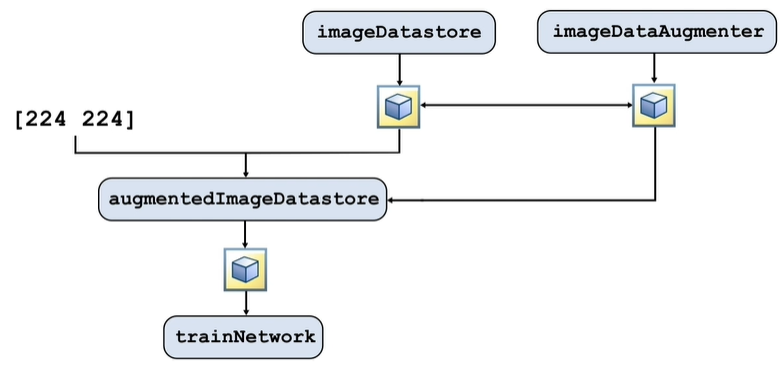

Las imágenes del almacén de datos pueden tener diferentes tamaños. Para cambiar automáticamente el tamaño de las imágenes de entrenamiento, utilice un almacén de datos de imágenes aumentado ([augmentedImageDatastore](https://es.mathworks.com/help/deeplearning/ref/augmentedimagedatastore.html?s_tid=doc_ta)). El aumento de datos también ayuda a evitar que la red se sobreajuste y memorice los detalles exactos de las imágenes de entrenamiento. 

**Se pide:**

- Utilice la función [imageDataAugmenter](https://es.mathworks.com/help/deeplearning/ref/imagedataaugmenter.html?s_tid=doc_ta) para definir las operaciones de aumento adicionales que desea realizar en las imágenes de entrenamiento. En nuestro caso: **a)** voltear aleatoriamente las imágenes de entrenamiento a lo largo del eje vertical y **b)** translaciones aleatorias de hasta 30 píxeles en horizontal y vertical. 

- Utilice la función [augmentedImageDatastore](https://es.mathworks.com/help/deeplearning/ref/augmentedimagedatastore.html?s_tid=doc_ta) para cambiar automáticamente el tamaño de las imágenes de **entrenamiento**, **validación**,  y **test**. En el caso de las imágenes de **entrenamiento** añada también las operación de aumento de datos definidas previamente en `imageAugmenter`.

% se especifican las operaciones para el Data Aumetation
pixelRange = [-30 30];
imageAugmenter = imageDataAugmenter( ); % RELLENAR AQUÍ

inputSize = [224 224 3];
% cambio del tamaño de las imágenes con Data Aumentation
aug_flowers_Train = augmentedImageDatastore( ); % RELLENAR AQUÍ
% cambio del tamaño de las imágenes  sin Data Aumentation
aug_flowers_Val = augmentedImageDatastore( ); % RELLENAR AQUÍ
aug_flowers_Test = augmentedImageDatastore( ); % RELLENAR AQUÍ

# `2. Modified Network`

###     2.1) Seleccionar una red preentrenada y prepararla para el entrenamiento

Para abrir Deep Network Designer, en la pestaña **Apps**, en **Machine Learning and Deep Learning**, haga clic en el icono de la app. Como alternativa, puede abrir la app desde la línea de comandos:

deepNetworkDesigner

Deep Network Designer proporciona una selección de redes de clasificación de imágenes que han aprendido representaciones ricas en características adecuadas para una amplia gama de imágenes. La transferencia del aprendizaje funciona mejor si las imágenes son similares a las imágenes utilizadas originalmente para entrenar la red.

Seleccione **GoogLeNet** de la lista de redes preentrenadas y haga clic en **Open**.

Explore la gráfica de red. Para ampliarla con el ratón, utilice **Ctrl** + la rueda de desplazamiento. Para desplazarse, utilice las teclas de flecha o mantenga pulsada la rueda de desplazamiento y arrastre el ratón. Seleccione una capa para ver sus propiedades. Quite la selección de todas las capas para ver el resumen de la red en el panel **Properties**.

Seleccione la capa de entrada de imagen, `'input'`. Puede ver que el tamaño de entrada para esta red es de 224 por 224 por 3 píxeles.

Para usar una red preentrenada para la transferencia del aprendizaje, debe modificar el número de clases de forma que coincida con el nuevo conjunto de datos. 

En primer lugar,  desbloquee la capa totalmente conectada (`fullyConnectedLayer`). Las capas totalmente conectadas necesitan un número determinado de neuronas.  En el panel **Properties**, establezca **OutputSize** en `5` (para los 5 tipos de flores).

***NOTA****: Antes de la versión R2023b: Para adaptar la red a los nuevos datos, debe remplazar las capas en vez de desbloquearlas. En las nuevas versiones puede hacer clic en ****Unlock Layer**** y modificar los parámetros.*

Para utilizar la red, debe exportarla. En la barra de herramientas, haga clic en **Expor**t y guarde la red con el nombre: **net_flowers **(por defecto el nombre de la red es **net**`_1`). Una vez guardada en el espacio de trabajo la puede utilizar para el entrenamiento con los datos de especies de flores.

# `3. Training Algorithm Options`

### **    3.1) **Establecer opciones de entrenamiento

Puede ver las opciones disponibles para un algoritmo de entrenamiento específico utilizando la función `trainingOptions`.

Con esto se crea una variable `options` que contiene las opciones predeterminadas para el algoritmo de  entrenamiento “gradiente descendente estocástico con momento” (SGDM).

% Ejecute para ver las opciones por defecto
options = trainingOptions("sgdm")

**Se pide:**

- Especifique las siguientes opciones de entrenamiento:

- Entrenar usando el optimizador "`sgdm`" (stochastic gradient descent with momentum).

- Por lo general, el entrenamiento se realiza conservando los valores predeterminados de la mayoría de las opciones. Sin embargo, en la  transferencia del aprendizaje, se suele comenzar con un valor de `InitialLearnRate` menor que el valor predeterminado de `0.01`. En nuestro caso lo vamos a fijar a `0.001`.

- Una época (`epoch`) es un ciclo de entrenamiento completo en el conjunto total de datos de entrenamiento. Para la transferencia del aprendizaje, no es necesario entrenar durante tantas épocas. Para reducir el tiempo de entrenamiento en la CPU, el número máximo de épocas (`MaxEpochs`) se limita a **1**, ya que por defecto son 30. Después puede probar a aumentarlas. 

- Especifique los datos de validación (`ValidationData`) y la frecuencia de validación (ValidationFrequency), cada cuántas iteraciones se realiza la validación, por ejemplo **10**.

- Especifique el tamaño de minilote (`MiniBatchSize`), es decir, cuántas imágenes se pueden utilizar en cada iteración. Un minilote es un subconjunto del conjunto de entrenamiento que se usa  para evaluar el gradiente de la función de pérdida y actualizar los  pesos. Utilice **16**.

- Muestre el progreso del entrenamiento en una gráfica y monitorice la métrica de precisión (`Plots="training-progress"`).

- Deshabilite la salida detallada (`Verbose=false`).

options = trainingOptions("sgdm",  );  % RELLENAR AQUÍ


# `4. Entrenar la red`

Entrene la red neuronal con la función [`trainnet`](https://www.mathworks.com/help/releases/R2024a/deeplearning/ref/trainnet.html). (para versiona anteriores a R2023b se deería utilizar [trainNetwork](https://es.mathworks.com/help/deeplearning/ref/trainnetwork.html)) Para las tareas de clasificación, utilice la pérdida de entropía cruzada. De forma predeterminada, la función `trainnet` usa una GPU en caso de que esté disponible. Para utilizar una GPU se requiere una licencia de Parallel Computing Toolbox™ y un dispositivo GPU compatible. Para obtener información sobre los dispositivos compatibles, consulte [GPU Computing Requirements](https://www.mathworks.com/help/releases/R2024a/parallel-computing/gpu-computing-requirements.html) (Parallel Computing Toolbox). De lo contrario, la función `trainnet` usa la CPU. Para especificar el entorno de ejecución, utilice la opción de entrenamiento `ExecutionEnvironment`.

flowers_net = trainnet(aug_flowers_Train, net_flowers, "crossentropy", options);

**Nota**: si este proceso tarda demasiado puede cargar alguna de las siguientes redes, que ya han sido entrenadas:

-  `"net_flowers1_sgdm.mat"``: `entrenada con epoch=1 usando el optimizador "`sgdm`" y carga la red: **flowernet1**

- `"net_flowers10_sgdm.mat"``: `entrenada con epoch=10 usando el optimizador "`sgdm`" y carga la red: **flowernet10**

- `"net_flowers1_adam.mat"``: `entrenada con epoch=1 usando el optimizador "adam" y carga la red: **flowernet1_adam**

- `"net_flowers10_adam.mat"``: `entrenada con epoch=10 usando el optimizador "adam" y carga la red: **flowernet10_adam**

# **Probar la red entrenada**

Compruebe el funcionamiento de la red entrenada con** epoch=1** y con **epoch=10** y compárelas

**Se pide:**

- Clasifique las imágenes de prueba. Para hacer predicciones con varias observaciones utilice la función [`minibatchpredict`](https://www.mathworks.com/help/releases/R2024a/deeplearning/ref/minibatchpredict.html). Para convertir las puntuaciones de predicción en etiquetas, utilice la función [`scores2label`](https://es.mathworks.com/help/deeplearning/ref/scores2label.html?searchHighlight=scores2label&s_tid=srchtitle_support_results_1_scores2label). La función `minibatchpredict` usa automáticamente una GPU en caso de que esté disponible.

- Evalúe el clasificador utilizando los resultados obtenidos para el conjunto de test, generando la matriz de confusión y calculando a partir de ésta los siguientes parámetros: `Accuracy, Macro_Recall, Macro_Precision y Macro_F1_score`. Nota: utilice la función `multiclass_scores` creada en el ejercico `T5_ex03_SVMHOGDigit_2026.mlx`

classNames = categories(flowerNames);
numClasses = numel(classNames);

flwrPredsScores = minibatchpredict( ); % RELLENAR AQUÍ
flwrPredsLabels = scores2label( ); % RELLENAR AQUÍ

figure
confMat = confusionchart( ); % RELLENAR AQUÍ

CM = confMat.NormalizedValues;
% Se añaden título
confMat.Title = 'clasificador de Flores con GoogLeNet';
% Se añaden resúmenes de columnas y filas.
confMat.RowSummary = 'row-normalized';
confMat.ColumnSummary = 'column-normalized';

[ClassScores, MacroScores] = multiclass_scores(CM);

CScores = array2table(ClassScores,'RowNames',classNames,'VariableNames',{'Recall','Precision','F1_Score'})
GScores = array2table(MacroScores,'RowNames',{'Global'},'VariableNames',{'Macro-Recall', 'Macro-Precision','Macro-F1'})

# FUNCIONES

function [ClassScores, GlobalScores] = multiclass_scores(CM)

    Recall = [];
    Precision = [];
    F1_Score = [];
    for i=1 : size(CM,1)
        Recall(i) = []; % COMPLETAR AQUÍ!!!!
        Precision(i) = []; % COMPLETAR AQUÍ!!!!
        F1_Score(i) = []; % COMPLETAR AQUÍ!!!!
    end

    ClassScores = [Recall' Precision' F1_Score'];
      
    Macro_Recall = []; % COMPLETAR AQUÍ!!!!
    Macro_Precision = []; % COMPLETAR AQUÍ!!!!
    Macro_F1 = []; % COMPLETAR AQUÍ!!!!

    GlobalScores = [Macro_Recall Macro_Precision Macro_F1];
end
